# Segment Defect Demo

Made by Andy Viche

## Introduction

This script is a demo comparing my classical detection functions against the AI's defect mask. The AI mask was trained on clean images, defect images, and the ground truth masks. Unlike the main image processing pipeline with the hybrid inspection function, this demo showcases the comparison of classical vs AI defect masks across all three datasets. From testing, the AI's ability to capture the defect's shape (recall) in an image across all three datasets was consistently over 90%, but with a tendency to over-flag/inflate the defect area. (mentioned in `trainSegmentDefect.m)`

%% 
% Defining the Datasets and preparing their respective Functions

    datasets = struct([]);
    datasets(1).name          = '01'; 
    datasets(1).classicalFcn  = @ringContinuityDetection; 
    
    datasets(2).name          = '02';
    datasets(2).classicalFcn  = @combineBrushScratch; 
    
    datasets(3).name          = '03';
    datasets(3).classicalFcn  = @bleedDetection;

PIXEL_IDS = [0 255];


## Selections

Select a dataset and a sample image from that dataset (1-10 = clean image; 11-20 = defect image)

    %% Pick a dataset
    selectedDataset = '01';
    
    %% Pick an image from the dataset
    imageIndex = 11;

NOTE: It will take a while to load on running a dataset for the first time. There will be 3 outputs: A Comparison Table, Original Image with Side-by-Side comparisons, and a Defect Overlay. Make sure to press "Run All"

## Results

The table consists of the mask's IoU, Recall, and Precision. Recall is the ratio of correctly detected targets to all actual targets; it serves as a measure of how much of the defect was detected by that specific method. IoU is the Intersection over Union; IoU measures how precisely a mask outlines an object's true shape. Precision is the the ratio of true positives to all predicted positives; Precision measures how correctly pixels are marked against the ground truth mask. All of these measurements rely on a relative comparison of the chosen method (Classical or AI) against the ground-truth (GT) mask, where the GT mask is pure black and white image of the decisive defect location and shape. 

The Side-by-Side comparison is then the visual representation meant to complement this table, with the two methods compared against the GT mask. 

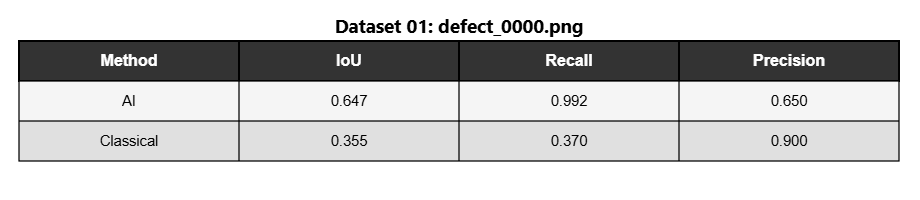


% ---- Automated Section -----------------------------------------
% Path Setup
% Get the full path and filename of the active live script in the editor
try
    scriptDir = fileparts(matlab.desktop.editor.getActiveFilename());
catch
    scriptDir = fileparts(mfilename("fullpath"));
end

repoDir = fileparts(scriptDir);   % scripts/ -> repo root

cfg = datasets(strcmp({datasets.name}, selectedDataset));

sampleDir = fullfile(repoDir, 'imageSampleSets', sprintf('sample_test_%s', cfg.name));
imagesDir = fullfile(sampleDir, 'images');
masksDir  = fullfile(sampleDir, 'masks');

addpath(genpath(repoDir)); % Create path for everything else
 
msg = sprintf(['Could not find imageSampleSets/sample_test_%s/images and /masks.\n', ...
    'Make sure the repo was cloned (not just this one file downloaded), ', ...
    'and that imageSampleSets/sample_test_%s/ contains the demo images/masks.'], cfg.name, cfg.name);
assert(exist(imagesDir, 'dir') == 7 && exist(masksDir, 'dir') == 7, msg);
 

% classNames is a fixed convention across this whole pipeline (see
% trainSegmentDefect.m)
classNames = ["background", "defect"];
defectClass = classNames(strcmpi(classNames, 'defect'));
 
imdsAll = imageDatastore(imagesDir);
pxdsAll = pixelLabelDatastore(masksDir, classNames, PIXEL_IDS);
 
idx = min(imageIndex, numel(imdsAll.Files));   % guard in case a dataset has <15
I    = readimage(imdsAll, idx);
gtC  = readimage(pxdsAll, idx);
gtMask = gtC == defectClass;
 
% Run both detectors on just this one image
maskAI = segmentDefect(I, cfg.name);
if ~isequal(size(maskAI), size(gtMask))
    maskAI = imresize(logical(maskAI), size(gtMask), 'nearest');
end
 
[maskClassical, ~] = cfg.classicalFcn(I, false);
if ~isequal(size(maskClassical), size(gtMask))
    maskClassical = imresize(logical(maskClassical), size(gtMask), 'nearest');
end
 
% Score this one image
isCleanImage = ~any(gtMask(:));
 
[~, fname] = fileparts(imdsAll.Files{idx});

if isCleanImage
    % IoU/Recall/Precision are undefined when there's no true defect
    % region at all
    % Percentage flagged (a pure false-positive measure) is 
    % more the meaningful thing to show instead.
    pctFlaggedAI        = 100 * nnz(maskAI) / numel(maskAI);
    pctFlaggedClassical = 100 * nnz(maskClassical) / numel(maskClassical);
 
    drawMetricsTable({'Method','Percentage Falsely Flagged'}, ...
        {'AI', sprintf('%.2f%%', pctFlaggedAI); ...
         'Classical', sprintf('%.2f%%', pctFlaggedClassical)}, ...
        sprintf('Dataset %s: %s.png', cfg.name, fname));
 
    fprintf(['This is a clean (defect-free) image', ...
             'No true defect region detected. ', ...
             'Showing false-positive area instead.\n']);
 
    aiIoUForTitle = 0; classicalIoUForTitle = 0;   % just for figure titles below
else
    % When defect
    aiM        = singleImageMetrics(maskAI, gtMask);
    classicalM = singleImageMetrics(maskClassical, gtMask);
 
    drawMetricsTable({'Method','IoU','Recall','Precision'}, ...
        {'AI',        sprintf('%.3f', aiM.IoU),        sprintf('%.3f', aiM.Recall),        sprintf('%.3f', aiM.Precision); ...
         'Classical', sprintf('%.3f', classicalM.IoU), sprintf('%.3f', classicalM.Recall), sprintf('%.3f', classicalM.Precision)}, ...
        sprintf('Dataset %s: %s.png', cfg.name, fname));
 
    aiIoUForTitle = aiM.IoU; classicalIoUForTitle = classicalM.IoU;
end

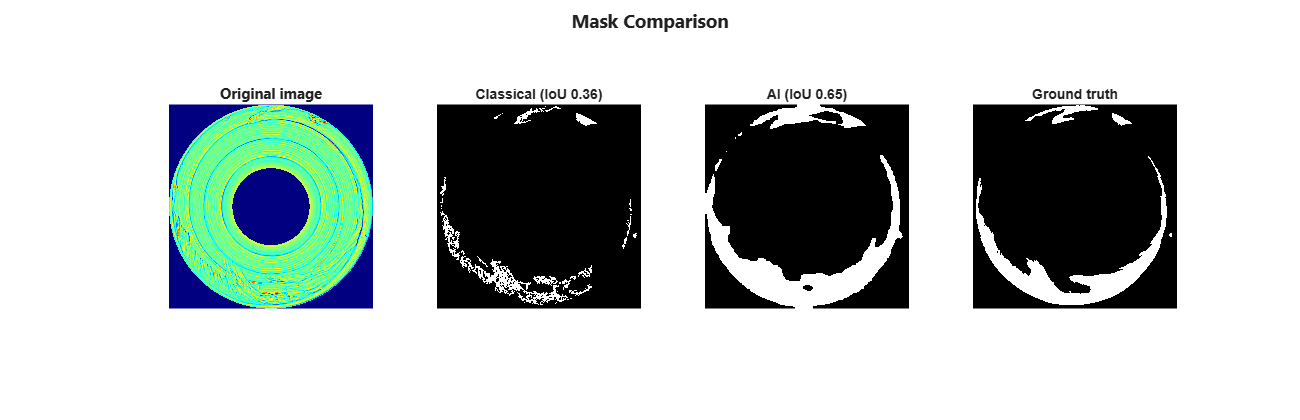

 

% --- Figure 1: Original image & Three masks ---
figure('Position', [50 50 1300 420]);

subplot(1,4,1); imshow(I); 
title(sprintf('Original image'), 'Interpreter', 'none', ...
    'FontWeight', 'bold', 'FontName', 'Segoe UI', 'FontSize', 11);
subplot(1,4,2); imshow(maskClassical); 
title(sprintf('Classical (IoU %.2f)', classicalIoUForTitle));
subplot(1,4,3); imshow(maskAI); 
title(sprintf('AI (IoU %.2f)', aiIoUForTitle));
subplot(1,4,4); imshow(gtMask); 
title('Ground truth');

sgtitle(sprintf('Mask Comparison'), 'Interpreter', 'none', ...
    'FontWeight', 'bold', 'FontName', 'Segoe UI', 'FontSize', 14);

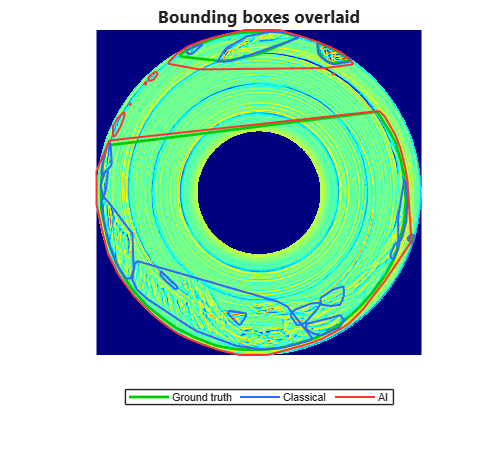

 
% --- Figure 2: Boundary overlay alone ---
figHandle = figure('Position', [1250 520 500 450]);
clf(figHandle);        % clear the whole figure
ax3 = axes(figHandle);
imshow(I, 'Parent', ax3); hold(ax3, 'on');
hGT         = drawBoundingBoxes(ax3, gtMask, [0 0.8 0], 2);            % green -- ground truth
hClassical  = drawBoundingBoxes(ax3, maskClassical, [0.2 0.4 1], 1.5);  % blue -- classical
hAI         = drawBoundingBoxes(ax3, maskAI, [1 0.2 0.2], 1.5);         % red -- AI
hold off;
legend([hGT hClassical hAI], {'Ground truth','Classical','AI'}, ...
    'Location', 'southoutside', 'Orientation', 'horizontal', 'FontSize', 8);
title(sprintf('Bounding boxes overlaid'), 'Interpreter', 'none', ...
    'FontWeight', 'bold', 'FontName', 'Segoe UI', 'FontSize', 13);







%% -------Local functions--------
function drawMetricsTable(headers, rows, figTitle)
% Draws a simple bordered table as a regular figure (docks inline in
% the Live Script, same as any other figure() call)
nCols = numel(headers);
nRows = size(rows, 1);

cellW = 220; cellH = 40; marginX = 20; marginY = 40;
figW = cellW * nCols + 2 * marginX;
figH = cellH * (nRows + 1) + 2 * marginY;

figure('Position', [80 80 figW figH]);
ax = axes('Units', 'pixels', 'Position', [marginX marginY cellW*nCols cellH*(nRows+1)]);
axis(ax, [0 nCols 0 nRows+1]);
set(ax, 'YDir', 'reverse');
axis(ax, 'off');
hold(ax, 'on');

headerColor = [0.20 0.20 0.20];
rowColors = {[0.96 0.96 0.96], [0.88 0.88 0.88]};   % light zebra striping

% Header row
for j = 1:nCols
    rectangle(ax, 'Position', [j-1, 0, 1, 1], 'FaceColor', headerColor, 'EdgeColor', 'k', 'LineWidth', 1.5);
    text(ax, j-0.5, 0.5, headers{j}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
        'FontWeight', 'bold', 'Color', 'w', 'FontSize', 12);
end
% Data rows
for i = 1:nRows
    rc = rowColors{mod(i-1, 2) + 1};
    for j = 1:nCols
        rectangle(ax, 'Position', [j-1, i, 1, 1], 'FaceColor', rc, 'EdgeColor', 'k', 'LineWidth', 1);
        text(ax, j-0.5, i+0.5, rows{i,j}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
            'Color', 'k', 'FontSize', 11);
    end
end

    if nargin > 2 && ~isempty(figTitle)
    t = title(ax, figTitle, 'Color', 'k', 'Interpreter', 'none', ...
        'FontWeight', 'bold', 'FontName', 'Segoe UI', 'FontSize', 14);
    t.Visible = 'on';
    end
end

 
function [mask, props] = combineBrushScratch(I, showDebug)
% Combines the brush and scratch defects and their evidence metrics
    [brushMask, brushProps] = brushDetection(I, showDebug);
    [scratchMask, scratchProps] = scratchDetection(I, showDebug);
    
    mask = brushMask | scratchMask;
    props = struct('Brush', brushProps, 'Scratch', scratchProps);
end
 
function m = singleImageMetrics(pred, gt)
% Calculates the metrics for the table on a per-image basis
% Tp = true pos, fn = false neg, fp = false pos
    pred = logical(pred); gt = logical(gt);
    tp = nnz(pred & gt); fp = nnz(pred & ~gt); fn = nnz(~pred & gt);
    m.IoU       = safeDiv(tp, tp+fp+fn);
    m.Recall    = safeDiv(tp, tp+fn);
    m.Precision = safeDiv(tp, tp+fp);
end
 
function v = safeDiv(num, den)
% Don't divide by zero
    if den == 0, v = 0; else, v = num/den; end
end

function h = drawBoundingBoxes(ax, mask, color, lineWidth)
% Actually draw convex hull. I just did not want to redo/change all variable
% names, so it is called bounding box
    stats = regionprops(mask, 'ConvexHull');
    allX = [];
    allY = [];
    for k = 1:numel(stats)
        ch = stats(k).ConvexHull;   % [x, y] pairs, already closed
        allX = [allX; ch(:,1); NaN];
        allY = [allY; ch(:,2); NaN];
    end
    if isempty(allX)
        allX = nan; allY = nan;
    end
    h = plot(ax, allX, allY, 'Color', color, 'LineWidth', lineWidth);
end
%% 